## ECEN 142L Communications and Networking Lab

## Lab 3: Error Curves

Kai Hoshide, Ryan Kinris, Dylan Thornburg

Signal to noise ratio (SNR) is one of the most important quantities we can measure in a communication system - it affects the performance of the systems we design, as well as the choices we make during the design process. Today we are going to take a closer look at bit, block, and symbol errors, and how different SNR values change them in some basic systems.

Today’s Objective: Learn about error rates under differing SNR regimes by plotting error curves.

**Part 1: BPSK Error Rates**

To start, we are going to be taking a look at a simple Binary Phase Shift Keying (BPSK) system. In BPSK we only have 2 possible symbols: +1 and -1. Let’s take a look at how the error rates change for 10 different levels of SNR.

Step 1:

Let’s start out by initializing some variables. We will want to keep track of the bit errors, block errors, and symbol errors for 10 different values of SNR - create a variable for each error count (as well as SNR and SNR in dB) and fill it with ten zeros, like below:

    snr_db = zeros(1,10);

Next, let’s define our loop. Create a for loop that will loop 10 times, once for each value of SNR.

The SNR values won’t be very interesting at very low SNR rates, so let’s start at 5.

The code will look something like this:

    snr_db(i) = 4 + i; % 5 6 7 8 ...

    snr(i) = 10.^(snr_db(i)/10);

Finally, create four new variables, n_loops, n_symbol_errors, n_bit_errors, and n_block_errors, and set each of them to be zero.

Step 2:

Next, let’s create our BPSK simulation. We will start by creating a while loop like so:

    while n_symbol_errors < 100

The reason we are going to be looping until we get at least 100 symbol errors is so that we can get a statistically significant sample.

Inside the while loop, create a variable tx_signal, which will hold the BPSK signal we want to send. For our signal, our block size will be 100, so we want tx_signal to be a 100x1 vector. Remember that BPSK signals are +1 and -1, fill tx_signal.

Now we will corrupt the signal with some noise. Add the code below to your program:

    noise = 1/sqrt(snr(i))*randn(100,1);

Looking at that line, we can see that the noise value depends on SNR which should make sense - as SNR goes up, the amount of noise in our signal should be less. Create a variable rx_signal that is the BPSK signal you generated plus the noise.

Now we can decode - in BPSK, decoding is as simple as extracting the sign of the symbols. Create a variable rx_decoded and decode the signal. For help, see Sign function (signum function) - MATLAB sign.

With the decoded signal, we can move on to the most important part: counting the symbol errors, which is simply finding the number of differences between the decoded signal and the transmitted signal. Create a variable called cur_n_symbol_errors that stores the number of symbols errors in the current block. (Hint: MATLAB has an operator that might be helpful.)

To finish out the while loop, update n_symbol_errors, n_bit_errors, n_block_errors , and n_loops. For BPSK, the number of symbol errors and the number of bit errors are the same. Also, the number of block errors is equal to the number of blocks in which at least one symbol is decoded incorrectly.

Step 3:

Once we break out of the while loop, we can calculate our symbol error, bit error, and block error rates for the current value of SNR. In BPSK, symbol errors and bit errors are the same, so we can update those variables with the amount of errors we saw, scaled by the number of loops and the block size. The block error rate is calculated as the ratio of the number of block errors to the number of loops, where a block error occurs if at least one bit in the block is decoded incorrectly.

Add code to update each of your error rate arrays with the correct values. In the same location, add the code:

    disp(i);

Finally, outside of the loop we can plot all of the data we collected. To do so, add this code:

    semilogy(snr_db,ber,snr_db,bler,'--');

    legend('Bit Error Rate','Block Error Rate (100 bits)') xlabel(' SNR (dB)')

    ylabel('Error Rate')

    grid;

We plot the error rates on a logarithmic axis to match the logarithmic scale of our SNR values in dB. Run your code and check the plots, keeping in mind that it might take a while. Watch the output of the disp command - what do you notice?

Inspect your plot, and comment on your results. Why is the block error so much higher than the bit error? Show your results from Part 1 to the TA.

clear; clc; close all;

snr_db = zeros(1,10);
snr = zeros(1,10);
ser = zeros(1,10);
ber = zeros(1,10);
bler = zeros(1,10);

for i = 1:10
    snr_db(i) = 4 + i; % 5 6 7 8 ...
    snr(i) = 10.^(snr_db(i)/10);

    n_loops = 0;
    n_symbol_errors = 0;
    n_bit_errors = 0;
    n_block_errors = 0;

    while (n_symbol_errors < 100)
        tx_signal = 2*randi([0 1], 100, 1) - 1; % Generates 100x1 vector with 0 or 2 in every spot minus 1 (-1,1) 
        noise = 1/sqrt(snr(i))*randn(100,1);
        rx_signal = tx_signal + noise;
        rx_decoded = sign(rx_signal);
        cur_n_symbol_errors = sum(rx_decoded ~= tx_signal);

        n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;
        n_bit_errors = n_bit_errors + cur_n_symbol_errors;
        n_block_errors = n_block_errors + sign(cur_n_symbol_errors);
        n_loops = n_loops + 1;
    end

    ser(i) = n_symbol_errors / (n_loops * 100);
    ber(i) = n_bit_errors / (n_loops * 100);
    bler(i) = n_block_errors / n_loops;

    disp(i);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



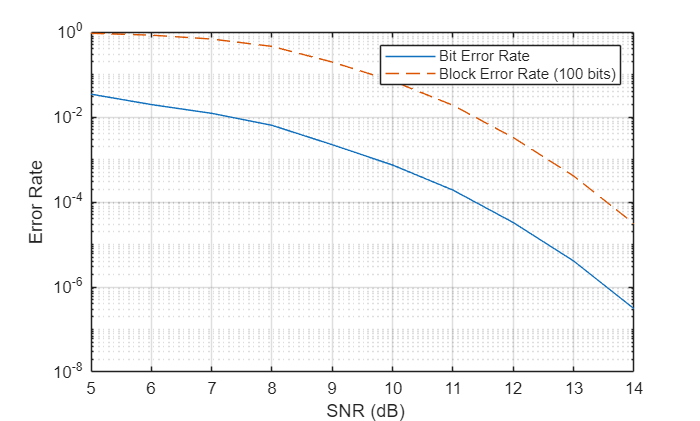


figure;
semilogy(snr_db,ber,snr_db,bler,'--');
legend('Bit Error Rate','Block Error Rate (100 bits)')
xlabel(' SNR (dB)')
ylabel('Error Rate')
grid;

What do you notice from the disp command?

**It displays the current loop #.**

Inspect your plot, and comment on your results.

**As SNR increases, error rate decreases for both, and block error rate is higher.**

Why is the block error so much higher than the bit error?

**Bit rate only accounts for individual bits. Because blocks are 100 bits, any one bit wrong now makes the whole block an error block.**

**Part 2: QPSK Error Rates**

Now we will take a look at a different type of system - QPSK. QPSK adds 2 more symbols on top of BPSK (notice that the symbols now are different than the bits). QPSK also introduces the Quadrature concept we learned in lecture. The symbols are:

    QPSK = [ 1+1j, 1-1j, -1+1j, -1-1j ];

We will repeat part 1 with this new scheme, and see how it differs.

Step 1:

Make a new section of code, and copy the complete part 1 - we only need to make a few changes to switch to QPSK.

The first change we need to make is in how we generate the signal and the noise. The noise is easy - we just need to add an imaginary component to the signal. It will look like this:

    noise = 1/sqrt(snr(i))*(randn(1,100) + 1j*randn(1,100));

To generate the QPSK signal, we just need to index the QPSK array above. For example, if we were to do this:

    tx_signal = QPSK([1, 1, 3, 2, 4]);

We would get the output

    [1+j, 1+j, -1+j, 1-j, -1-j ]

Which is exactly what we need. Create a signal QPSK_indices that is 100x1 vector of values between 1 and 4 and use it to generate the tx_signal.

Step 2:

We will need to update our decoding step so that we can work with the new imaginary values. Let's start by using the signum function again, but this time, we will slice the signal so that we are dealing with the real and imaginary values separately. Paste in the code below:

    decode_real = sign(real(rx_signal));

    decode_imag = sign(imag(rx_signal));

Now, following the same logic, create variables called real_errors and imag_errors that contain the codes that are in error.

Finally, let’s update the variables n_symbol_errors , n_bit_errors, and n_block_errors.

n_bit_errors is easy, it gets updated with the sum of the real errors and imaginary errors.

The total errors and block errors look a little different. Paste in the code below:

    cur_n_symbol_errors = sum(real_errors | imag_errors);

    n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;

    n_block_errors = n_block_errors + sign(cur_n_symbol_errors);

Step 3:

To view the QPSK plot, we need to make two more small changes. The first is to the BER array update - symbol error stays the same, but we now have to use more bits per symbol. How many bits are needed for 4 symbols? Scale the BER update by your answer.

We also need to add in the new values to the plot. Paste in the code below (your variables may differ):

    semilogy(snr_db,ser,snr_db,ber,'--',snr_db,bler,'-o')

    legend('Symbol Error Rate','Bit Error Rate','Block Error Rate (100 bits)')

Run your code and inspect your error curves. How much did the curve shift from your BPSK version? After 10 dB SNR how quickly does the curve decrease per 1 dB?

Show your results from Part 2 to the TA.

clear; clc; close all;

QPSK = [1+1j, 1-1j, -1+1j, -1-1j];

snr_db = zeros(1,10);
snr = zeros(1,10);
ser = zeros(1,10);
ber = zeros(1,10);
bler = zeros(1,10);

for i = 1:10
    snr_db(i) = 4 + i; % 5 6 7 8 ...
    snr(i) = 10.^(snr_db(i)/10);

    n_loops = 0;
    n_symbol_errors = 0;
    n_bit_errors = 0;
    n_block_errors = 0;

    while n_symbol_errors < 100
        QPSK_indices = randi([1 4], 1, 100);
        tx_signal = QPSK(QPSK_indices);
        noise = 1/sqrt(snr(i))*(randn(1,100) + 1j*randn(1,100));
        rx_signal = tx_signal + noise;

        decode_real = sign(real(rx_signal));
        decode_imag = sign(imag(rx_signal));
        real_errors = (decode_real ~= real(tx_signal));
        imag_errors = (decode_imag ~= imag(tx_signal));

        cur_n_symbol_errors = sum(real_errors | imag_errors);
        n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;
        n_bit_errors = n_bit_errors + sum(real_errors) + sum(imag_errors); % cur_n_symbol_errors;
        n_block_errors = n_block_errors + sign(cur_n_symbol_errors);
        n_loops = n_loops + 1;
    end
    ser(i) = n_symbol_errors / (n_loops * 100);
    ber(i) = n_bit_errors / (n_loops * 100 * 2);
    bler(i) = n_block_errors / n_loops;

    disp(i);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



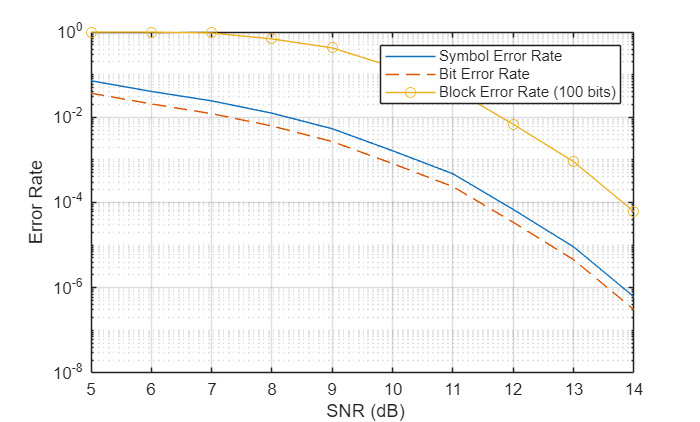


figure;
semilogy(snr_db,ser,snr_db,ber,'--',snr_db,bler,'-o')
legend('Symbol Error Rate','Bit Error Rate','Block Error Rate (100 bits)')
xlabel(' SNR (dB)')
ylabel('Error Rate')
grid;

How many bits are needed for 4 symbols?

**We need 2 bits.**

How much did the curve shift from your BPSK version?

**Block rate and symbol rate seemed to get a little worse, while bit rate seemed to stay about the same.**

After 10 dB SNR how quickly does the curve decrease per 1 dB?

**It decreases more quickly after 10 dB, and each additional 1 dB increase in SNR causes roughly an order of magnitude style decrease over the next few dB.**

**Part 3: Jakes fading model**

So far, we have assumed that the only non-ideal property of our channel is some added noise. In real wireless transmission, transmitted signals will bounce around and scatter, and these scattered versions will all arrive at the receiver with different amplitudes and phases, and the effects are even more pronounced if the transmitter is moving.

In the next few steps, we are going to add the features of this model (called a Jakes model, after William Jakes) to our QPSK system and see what it does to our error curves.

Step 1:

Once again, start a new section and copy the code from part 2. Next download the file Jakes.m from the lab camino page - this is the function that will do the hard part of the scattering calculations for us. Place the function in your working directory.

The Jakes function takes 3 arguments. The first is a time vector - this is the time for each bit in a “frame” of data. Remembering that our frame size is 100 bits, and that a frame is commonly 5ms long, create a time vector for one frame of QPSK data.

The next argument to the Jakes function is the number of echos the receiver will see.

To keep things simple, make this argument 1.

The final argument is the Doppler frequency. The Doppler frequency is defined as:

fdoppler = v * f / c

Where v is the velocity of motion in m/s, f is the carrier frequency, and c is 3e8, the speed of light. To start, let’s make v = 0.3, and the carrier frequency 2 GHz. Create a variable to store the doppler frequency that you calculate.

We will also need 2 new variables - snr_a_db, a length 10 array, and snr_a, a value which we can initialize to zero.

Step 2:

To add the Jakes model, we only need a few other changes. First, change the while loop end condition to be n_symbol_errors < 10000. Adding the scattering adds more variability, so we need to increase the number of samples we take to retain the statistical significance.

Next, let’s call the Jakes function. Add these lines before you generate the tx signal:

    alpha = Jakes(time_vec, 1, doppler);

    snr_a = snr_a + mean(abs(alpha).^2)*snr(i);

And we can also change the generation of the rx_signal:

    rx_signal = alpha.'.*tx_signal;

    rx_signal = rx_signal + noise;

These lines generate the scattering signal and add them into the received signal.

Because we change the received signal, we also need to update the decoding logic. Update the first few lines with this:

    decode_real = sign(real(rx_signal./alpha.'));

    decode_imag = sign(imag(rx_signal./alpha.'));

To finish off, we need to calculate the snr_a in db outside of the loop. Underneath the BER/SER/BLER calculations, add this line:

    snr_a_db(i) = 10*log10(snr_a / n_loops);

Finally, change your plot command to plot against snr_a_db instead of snr_db.

Step 3:

Run the finished code and carefully examine the results. Is it different from what you saw in part 2? What does this plot say about the effects of fading on a signal?

Show your results from Part 3 to the TA.

Now go back and try some different values of velocity and carrier frequency to see how the results change. Comment on your results. What happens to the BLER and BER as the velocity increases?

**v=.3**

clear; clc; close all;

QPSK = [1+1j, 1-1j, -1+1j, -1-1j];

snr_db = zeros(1,10);
snr = zeros(1,10);
snr_a_db = zeros(1,10);
ser = zeros(1,10);
ber = zeros(1,10);
bler = zeros(1,10);

frame_size = 100;
frame_time = 5e-3;
time_vec = linspace(0,frame_time,frame_size);

v = 0.3;
f = 2e9;
c = 3e8;
doppler = v * f / c;

for i = 1:10
    snr_db(i) = 4 + i; % 5 6 7 8 ...
    snr(i) = 10.^(snr_db(i)/10);
    snr_a = 0;

    n_loops = 0;
    n_symbol_errors = 0;
    n_bit_errors = 0;
    n_block_errors = 0;

    while n_symbol_errors < 10000
        alpha = Jakes(time_vec, 1, doppler);
        snr_a = snr_a + mean(abs(alpha).^2)*snr(i);
        QPSK_indices = randi([1 4], 1, 100);
        tx_signal = QPSK(QPSK_indices);
        noise = 1/sqrt(snr(i))*(randn(1,100) + 1j*randn(1,100));

        rx_signal = alpha.'.*tx_signal;
        rx_signal = rx_signal + noise;
        decode_real = sign(real(rx_signal./alpha.'));
        decode_imag = sign(imag(rx_signal./alpha.'));
        real_errors = (decode_real ~= real(tx_signal));
        imag_errors = (decode_imag ~= imag(tx_signal));

        cur_n_symbol_errors = sum(real_errors | imag_errors);
        n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;
        n_bit_errors = n_bit_errors + sum(real_errors) + sum(imag_errors);
        n_block_errors = n_block_errors + sign(cur_n_symbol_errors);
        n_loops = n_loops + 1;
    end

    ser(i) = n_symbol_errors / (n_loops * 100);
    ber(i) = n_bit_errors / (n_loops * 100 * 2);
    bler(i) = n_block_errors / n_loops;
    snr_a_db(i) = 10*log10(snr_a / n_loops);

    disp(i);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



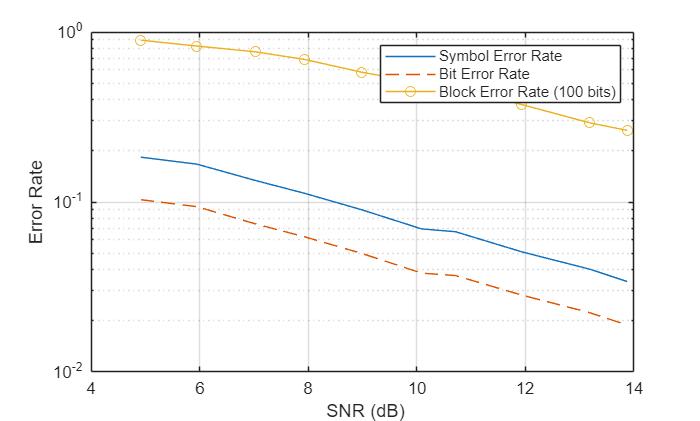


figure;
semilogy(snr_a_db,ser,snr_a_db,ber,'--',snr_a_db,bler,'-o')
legend('Symbol Error Rate','Bit Error Rate','Block Error Rate (100 bits)')
xlabel(' SNR (dB)')
ylabel('Error Rate')
grid;

**v=20**

clear; clc; close all;

QPSK = [1+1j, 1-1j, -1+1j, -1-1j];

snr_db = zeros(1,10);
snr = zeros(1,10);
snr_a_db = zeros(1,10);
ser = zeros(1,10);
ber = zeros(1,10);
bler = zeros(1,10);

frame_size = 100;
frame_time = 5e-3;
time_vec = linspace(0,frame_time,frame_size);

v = 20;
f = 2e9;
c = 3e8;
doppler = v * f / c;

for i = 1:10
    snr_db(i) = 4 + i; % 5 6 7 8 ...
    snr(i) = 10.^(snr_db(i)/10);
    snr_a = 0;

    n_loops = 0;
    n_symbol_errors = 0;
    n_bit_errors = 0;
    n_block_errors = 0;

    while n_symbol_errors < 10000
        alpha = Jakes(time_vec, 1, doppler);
        snr_a = snr_a + mean(abs(alpha).^2)*snr(i);
        QPSK_indices = randi([1 4], 1, 100);
        tx_signal = QPSK(QPSK_indices);
        noise = 1/sqrt(snr(i))*(randn(1,100) + 1j*randn(1,100));

        rx_signal = alpha.'.*tx_signal;
        rx_signal = rx_signal + noise;
        decode_real = sign(real(rx_signal./alpha.'));
        decode_imag = sign(imag(rx_signal./alpha.'));
        real_errors = (decode_real ~= real(tx_signal));
        imag_errors = (decode_imag ~= imag(tx_signal));

        cur_n_symbol_errors = sum(real_errors | imag_errors);
        n_symbol_errors = n_symbol_errors + cur_n_symbol_errors;
        n_bit_errors = n_bit_errors + sum(real_errors) + sum(imag_errors);
        n_block_errors = n_block_errors + sign(cur_n_symbol_errors);
        n_loops = n_loops + 1;
    end

    ser(i) = n_symbol_errors / (n_loops * 100);
    ber(i) = n_bit_errors / (n_loops * 100 * 2);
    bler(i) = n_block_errors / n_loops;
    snr_a_db(i) = 10*log10(snr_a / n_loops);

    disp(i);
end

     1

     2

     3

     4

     5

     6

     7

     8

     9

    10



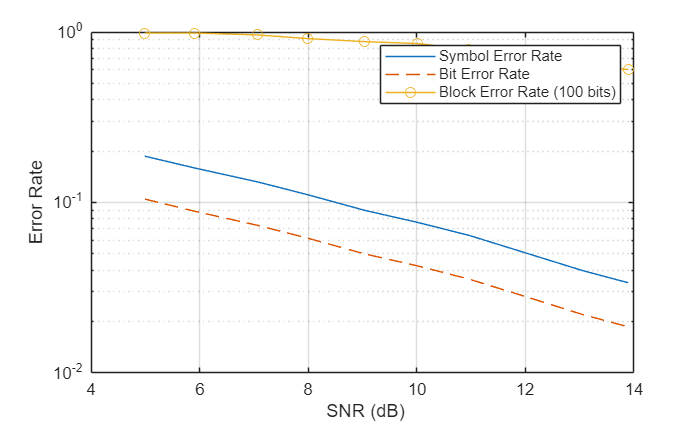


figure;
semilogy(snr_a_db,ser,snr_a_db,ber,'--',snr_a_db,bler,'-o')
legend('Symbol Error Rate','Bit Error Rate','Block Error Rate (100 bits)')
xlabel(' SNR (dB)')
ylabel('Error Rate')
grid;

Is it different from what you saw in part 2?

**Yes this is different. The decrease remains more linear and the error rate doesn't get as low.**

What does this plot say about the effects of fading on a signal?

**Fading on a signal causes higher error rates than just traditional noise. **

Try different values of velocity and carrier frequency and comment on results.

**Small changes in velocity didn't make that much of a difference, but there was a general trend of the higher the velocity, the higher the error rates for all measurements. Same with frequency.**

What happens to the BLER and BER as the velocity increases?

**They get higher.**

**Report:**

Submit your codes and answers to questions on camino. In addition, discuss the following questions with your partner and attach your answers to the end of your report.

1. What did you observe from the experiments?

**We observed that BPSK and QPSK are overall similar in performance with BPSK being slightly more resistant to traditional noise because of the fact that it has less chance for errors to happen in symbols and blocks. **

**We also saw that fading models, which sums multiple sinusoids to cause fluctuation of signal strength and quality, create significantly higher error rates than traditional noise.**

2. If you could expand this experiment how would you do it?

**I would try to implement some sort of real hardware interaction. It could serve students well to physically see the noise disrupt the signal.**

3. How does the experiment relate to the course topic?

**Well, the course is on networking and communications. We will have to deal with noise and interference in networking, and this lab helps us see the results of what noise can do to a signal.**

4. What did you learn from the experiment?

**The higher the SNR, the lower the error rate. BPSK and QPSK have the same bit error rates, but QPSK has worse symbol and block error rate. **

**Fading creates dynamic distortion, fundamentally interfering with the signal more which disrupts it more than noise.**